clear all;
clc

## Data

m = 4.639;
a = xlsread('Impact (25).xlsx');

f_a = a(1:292,5); 
t_a = a(1:292,2);
d_a = a(1:292,3);
vinit_a = a(1,6);


## Calculation of dtheo for cases a and b

intf_a = 1e-5*cumtrapz(f_a); % cumtrapz(f) = integral f.dn where dn = 1e5*dt
% Hence, required integral f.dt = 1e-5*cumtrapz(f)
vtheo_a = vinit_a + 9.8*t_a*0.001 - (1/m)*intf_a;
dtheo_a = 1000*1e-5*cumtrapz(vtheo_a); % 1000 is multiplied to convert dtheo into mm



## Calculation of fracture energy

frac_a = 0.001*trapz(d_a,f_a);

fractheo_a = 0.001*trapz(dtheo_a,f_a);


## Plots

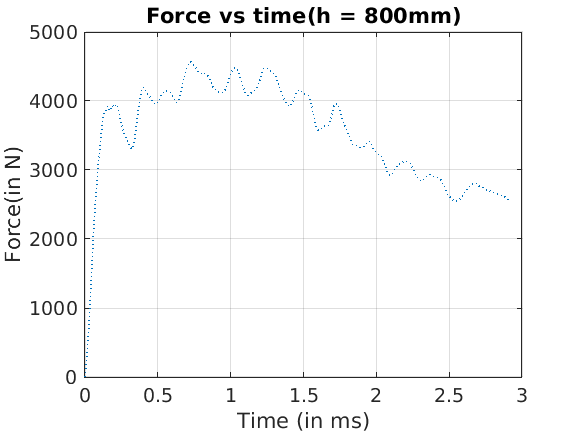

figure(1)
plot(t_a,f_a,':','Linewidth',1.2);
ylabel('Force(in N)','Fontsize',14);
xlabel('Time (in ms)','Fontsize',14);
title('Force vs time(h = 800mm)','Fontsize',14);
grid on;
ax = gca;
ax.FontSize = 14;
ax.XAxis.LineWidth = 1.2;
ax.YAxis.LineWidth = 1.2;

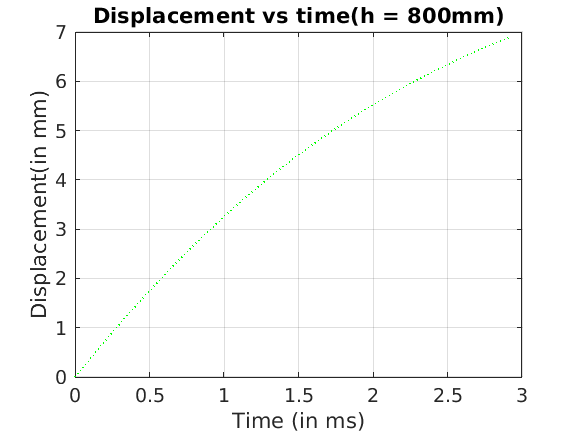


figure(2)
plot(t_a,d_a,'g:','Linewidth', 1.2);
ylabel('Displacement(in mm)','Fontsize',14);
xlabel('Time (in ms)','Fontsize',14);
title('Displacement vs time(h = 800mm)','Fontsize',14);
grid on;
ax = gca;
ax.FontSize = 14;
ax.XAxis.LineWidth = 1.2;
ax.YAxis.LineWidth = 1.2;

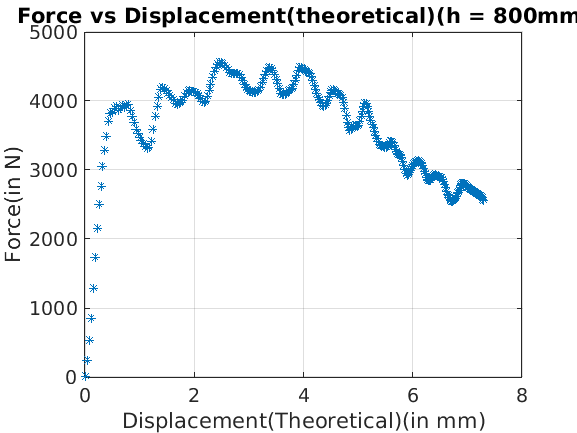


figure(3)
plot(dtheo_a,f_a,'*','Linewidth',1.2);
ylabel('Force(in N)','Fontsize',14);
xlabel('Displacement(Theoretical)(in mm)','Fontsize',14);
title('Force vs Displacement(theoretical)(h = 800mm)','Fontsize',14);
grid on;
ax = gca;
ax.FontSize = 14;
ax.XAxis.LineWidth = 1.2;
ax.YAxis.LineWidth = 1.2;

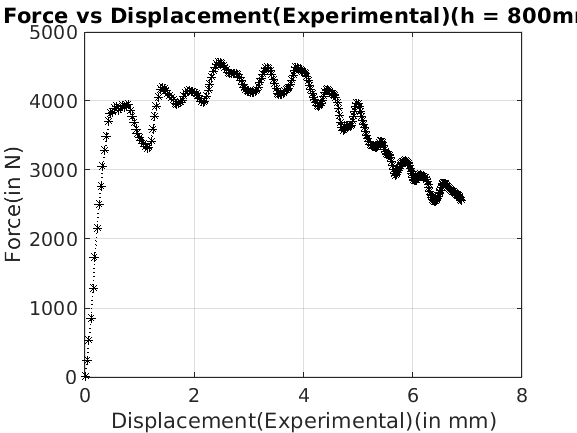


figure(4)
plot(d_a,f_a,'k:*','Linewidth',1.2);
ylabel('Force(in N)','Fontsize',14);
xlabel('Displacement(Experimental)(in mm)','Fontsize',14);
title('Force vs Displacement(Experimental)(h = 800mm)','Fontsize',14);
grid on;
ax = gca;
ax.FontSize = 14;
ax.XAxis.LineWidth = 1.2;
ax.YAxis.LineWidth = 1.2;


% figure(5)
% plot(t_b,f_b,'Linewidth',1.2);
% ylabel('Force(in N)','Fontsize',14);
% xlabel('Time (in ms)','Fontsize',14);
% title('Force vs time(h = 800mm)','Fontsize',14);
% grid on;
% ax = gca;
% ax.FontSize = 14;
% ax.XAxis.LineWidth = 1.2;
% ax.YAxis.LineWidth = 1.2;
% 
% figure(6)
% plot(t_b,d_b,'Linewidth',1.2);
% ylabel('Displacement(in mm)','Fontsize',14);
% xlabel('Time (in ms)','Fontsize',14);
% title('Displacement vs time(h = 800mm)','Fontsize',14);
% grid on;
% ax = gca;
% ax.FontSize = 14;
% ax.XAxis.LineWidth = 1.2;
% ax.YAxis.LineWidth = 1.2;
% 
% figure(7)
% plot(dtheo_b,f_b,'Linewidth',1.2);
% ylabel('Force(in N)','Fontsize',14);
% xlabel('Displacement(Theoretical)(in mm)','Fontsize',14);
% title('Force vs Displacement(theoretical)(h = 800mm)','Fontsize',14);
% grid on;
% ax = gca;
% ax.FontSize = 14;
% ax.XAxis.LineWidth = 1.2;
% ax.YAxis.LineWidth = 1.2;
% 
% figure(8)
% plot(d_b,f_b,'Linewidth',1.2);
% ylabel('Force(in N)','Fontsize',14);
% xlabel('Displacement(Experimental)(in mm)','Fontsize',14);
% title('Force vs Displacement(Experimental)(h = 800mm)','Fontsize',14);
% grid on;
% ax = gca;
% ax.FontSize = 14;
% ax.XAxis.LineWidth = 1.2;
% ax.YAxis.LineWidth = 1.2;